# Simulação: Projeto de controle digital

Especificações do sistema

clc;
clear;
s = tf('s');
P = 100;

K = 1/8; % divisor de tensão (24V/8 = 3V)
offset = 0;

Kp = 0.08;
Ki = 0.02;

N = 10 * 100;
n = 2;

Fs = 5e3;
Ts = 1/Fs;
Tsc = Ts/P;

T = 20e-3;
F = 1/T;

nBitsADC = 12;
Q = 2^nBitsADC;
ADC_Vmax = 3;

E = 24;

% Valores vindos do outro arquivo do matlab
R = 15.4;
L = 3.3e-3;
C = 30.17e-6;

F_lc = (1 / sqrt(L * C)) / (2 * pi)

F_lc = 504.4005

Buck -- Planta

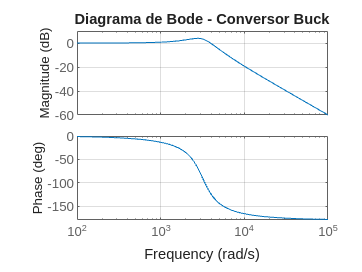

zeta = (1/(2*R)) * sqrt(L/C);
omega = 1 / sqrt(L * C);

Ps = omega^2 / (s^2 + 2*zeta*omega*s + omega^2);

bode(Ps);
grid on;
title('Diagrama de Bode - Conversor Buck');


Pz = c2d(Ps, Tsc);
[nPd, dPd] = tfdata(Pz, 'v');

a2 = dPd(2);
a3 = dPd(3);
b2 = nPd(2);
b3 = nPd(3);

Filtro anti-alising

alfa = 0.5; % escolher entre 0.5 < alpha < 1
f_AA = alfa*sqrt(Fs*F_lc)

f_AA = 794.0407

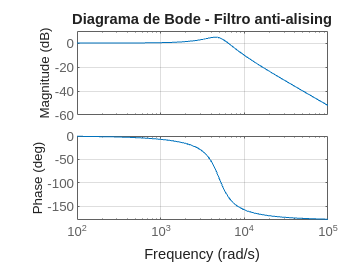


zeta_AA = 0.3; % escolher entre 0.1 <= zeta <= 0.4
omega_AA = 2 * pi * f_AA;

Ss = omega_AA^2 / (s^2 + 2*zeta_AA*omega_AA*s + omega_AA^2);

bode(Ss);
grid on;
title('Diagrama de Bode - Filtro anti-alising');


Sz = c2d(Ss, Tsc);
[nSd, dSd] = tfdata(Sz, 'v');

c2 = dSd(2);
c3 = dSd(3);
d2 = nSd(2);
d3 = nSd(3);

Inicialização dos vetores

x = 12*ones(1, N);
e = zeros(1, N);
u = zeros(1, N);
d = zeros(1, N);
t = zeros(1, N);

tc = zeros(1, N*P);
PWM = zeros(1, N*P);
y = zeros(1, N*P);
yr = zeros(1, N*P);
yng = zeros(1, N*P);
ys = zeros(1, N*P);
yns = zeros(1, N*P);

ynsT = zeros(1, N);
ynsR = zeros(1, N * P);
ymAD = zeros(1, N);
ym = zeros(1, N);

Simulação

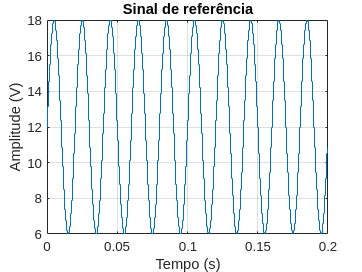

for k=3:N
    t(k) = (k-3)*Ts;
    
    % sinal de ref
    x(k) = x(k) + (6 * sin(2 * pi * F * t(k)));

    e(k) = x(k) - ym(k); %erro
    u(k) = u(k-1) + Kp*e(k) - Kp*Ki*e(k-1); %acao de controle
    
    if u(k) < 0 
        u(k) = 0; 
    end
    if u(k)>E 
        u(k) = E; 
    end
    
    % duty cycle
    d(k) = u(k) * P/E; % por que é P e n N?
    
    % super amostragem
    for cc=1:P
        kc = k * P + cc;
        tc(kc) = kc * Tsc;

        if cc <= d(k) 
            PWM(kc)=E; 
        end
        if cc>d(k) 
            PWM(kc)=0; 
        end

        y(kc+1) = -a2*y(kc) - a3*y(kc-1) + b2*PWM(kc) + b3*PWM(kc-1);
        yr(kc) = y(kc+1) + 0.1*rand(1);
        yng(kc) = K*yr(kc);
        ys(kc+1) = -c2*ys(kc) - c3*ys(kc-1) + d2*yng(kc) + d3*yng(kc-1); %medicao
        yns(kc+1) = ys(kc+1) + offset;
    end
    
    ynsT(k+1) = yns(kc+1);

    for i=(kc+1):(kc+1+P) 
        ynsR(i) = ynsT(k+1); 
    end

    ymAD(k+1) = round(ynsR(kc+1)*Q/ADC_Vmax);
    ym(k+1) = ( (ymAD(k+1) / Q*ADC_Vmax) - offset) / K;
    
end

ynsT(k+1)=[];
yns(kc+1)=[];

ymAD(k+1)=[];
ym(k+1)=[];
y(kc+1)=[];
ys(kc+1)=[];

figure;
stairs(t, x);
grid on;
title('Sinal de referência');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

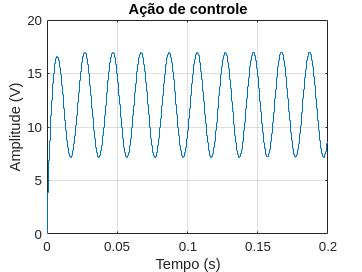


figure;
stairs(t, u);
grid on;
title('Ação de controle');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

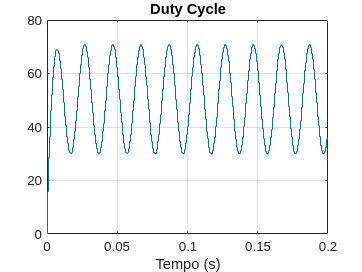


figure;
stairs(t, d);
grid on;
title('Duty Cycle');
xlabel('Tempo (s)');

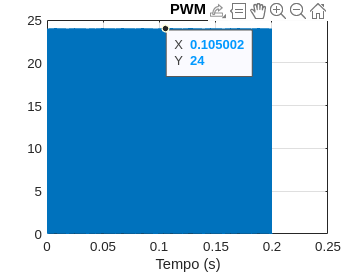


figure;
stairs(tc, PWM);
grid on;
title('PWM');
xlabel('Tempo (s)');

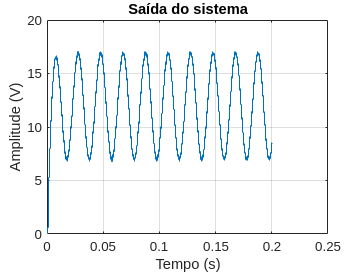


figure;
stairs(tc, y);
grid on;
title('Saída do sistema');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');

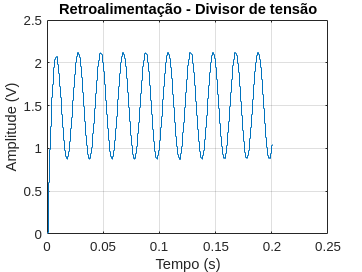


figure;
stairs(tc, ys);
grid on;
title('Retroalimentação - Divisor de tensão');
xlabel('Tempo (s)');
ylabel('Amplitude (V)');